
DIPlib 2.9 (Oct 17 2017 - Release [on Cygwin (with OpenMP)])
    Scientific Image Analysis Library
    Quantitative Imaging Group, Delft University of Technology 1995-2017
    info@diplib.org


dipIO 2.9 (Oct 17 2017 - Release)
    File I/O library for DIPlib
    Quantitative Imaging Group, Delft University of Technology 1999-2017
    info@diplib.org



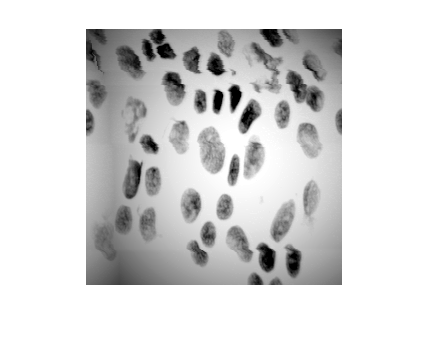

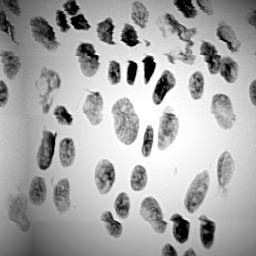

Displayed in figure 13


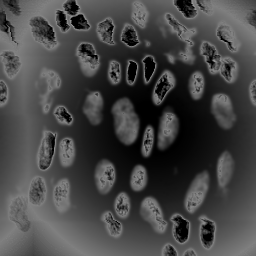

Displayed in figure 14


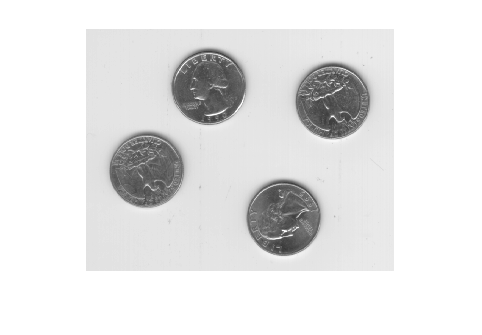

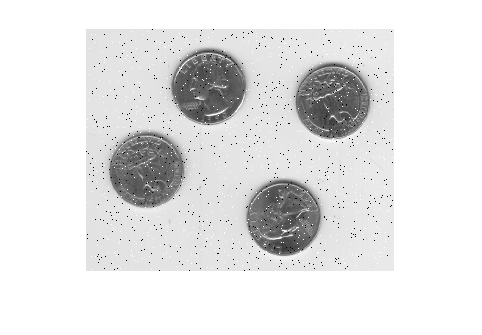

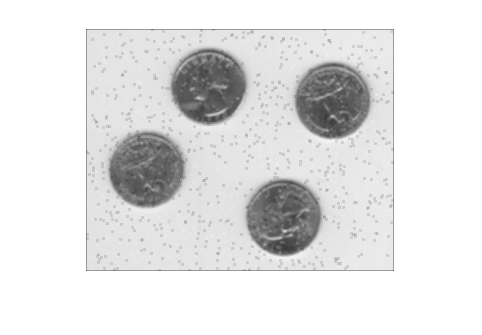

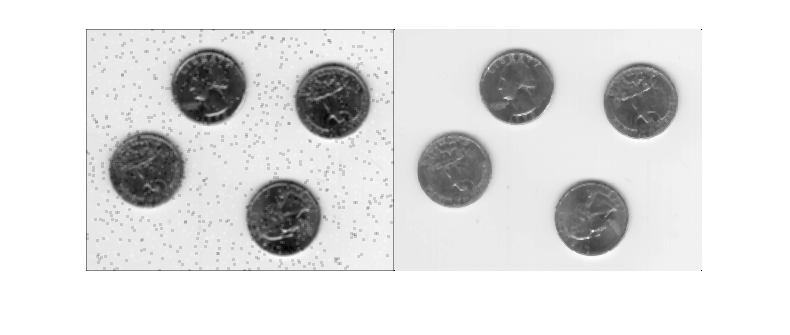

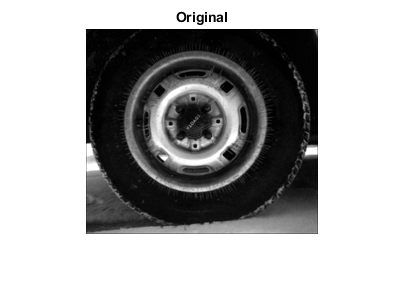

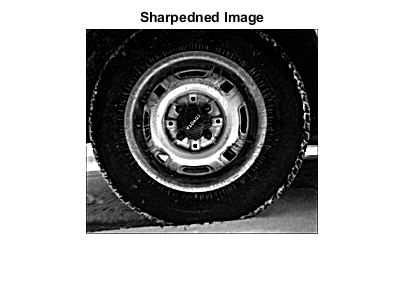

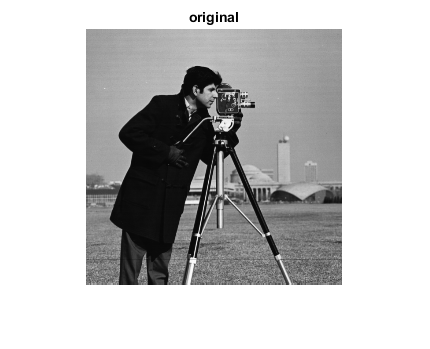

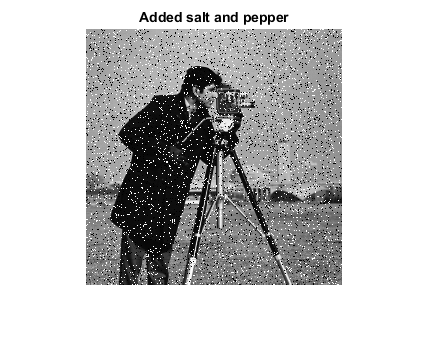

dipstart

**Q1: edge detection**--implement in matlab. 

**Ans: **I wanted to use 'egde' function to detect edges of the image, but since the edge function can only be applied to 2-dimensional images, I have to convert the image into 3 different channels (RGB), then apply the edge function to each of the channel then combine them into 1 at the end. But unfortunately, the idea was not successful since the edge function can only detect the edges of gray images, not colored image. 

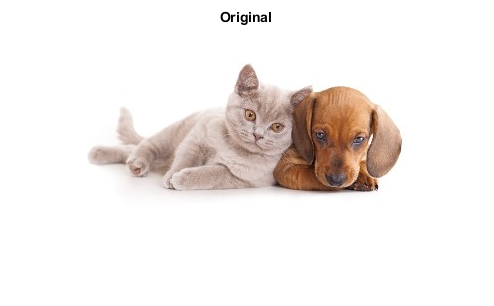

im0 = imread('puppy-and-kitten.jpg');
imshow(im0), title('Original')

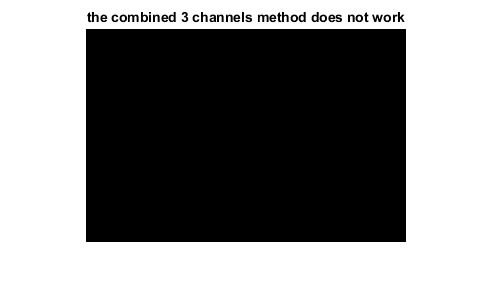

%convert image to 3 different channels
imR = im0(:,:,1);
imG = im0(:,:,2);
imB = im0(:,:,3);

%edge dection for each image
resR= edge(imR,'zerocross');
resG= edge(imG,'zerocross');
resB= edge(imB,'zerocross');

 res=im0;
 res(:,:,1)=resR; %putting R resultant in result image
 res(:,:,2)=resG; %putting  G resultant in result image
 res(:,:,3)=resB; %putting B resultant in result image

imshow(res); title('the combined 3 channels method does not work') %combined result does not work

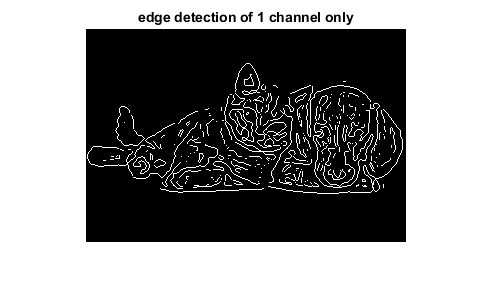

imshow(resG); title('edge detection of 1 channel only') %edge detection of one of the channel

**Q2:** use morphological operations to implement in matlab.

**Ans: **First, I convert the original image to binary image using 'im2bw', then I use function 'bwareafilt' with the second parament '2' in order to filter 2 biggest objects in the picture. 

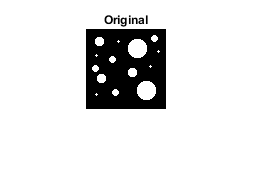

Image2 = imread('bubbles.png');
Image2 = im2bw(Image2,0.4);
imshow(Image2), title('Original')

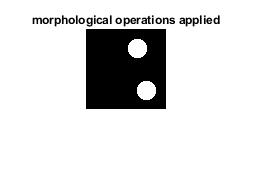


BW2 = bwareafilt(Image2, 2);
imshow(BW2), title('morphological operations applied')

**Q3:** When old documents are scanned it is sometimes difficult to read the text. 

**Ans:** I use imsharpen function to sharpen the image so the letters are much more visible. 

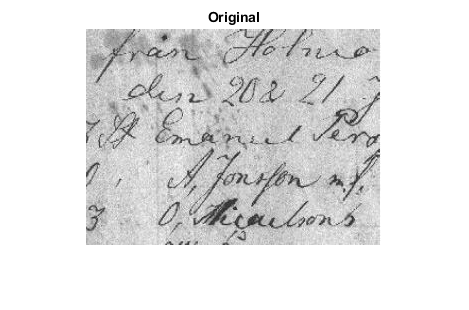

Image3 = imread('words.jpg');
imshow(Image3), title('Original')

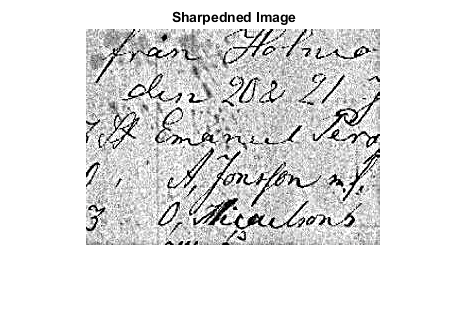

Sharpened = imsharpen(Image3,'Radius',3,'Amount',2);
imshow(Sharpened), title('Sharpedned Image')